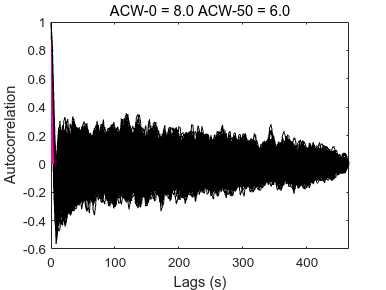

clear;clc;
file=readmatrix('9036.csv');
acwvalue=[];
for i=1:length(file(1,:))
    temp=[];
    x=file(:,i);
    if ~isnan(file(1,i))
        [acw_0,acw_50,~,~]=acw(x', 0.5, 1);
        temp=[i,acw_50,acw_0];
        acwvalue=[acwvalue;temp];
    else
        acwvalue=[acwvalue;[i,NaN,NaN]];
    end
end